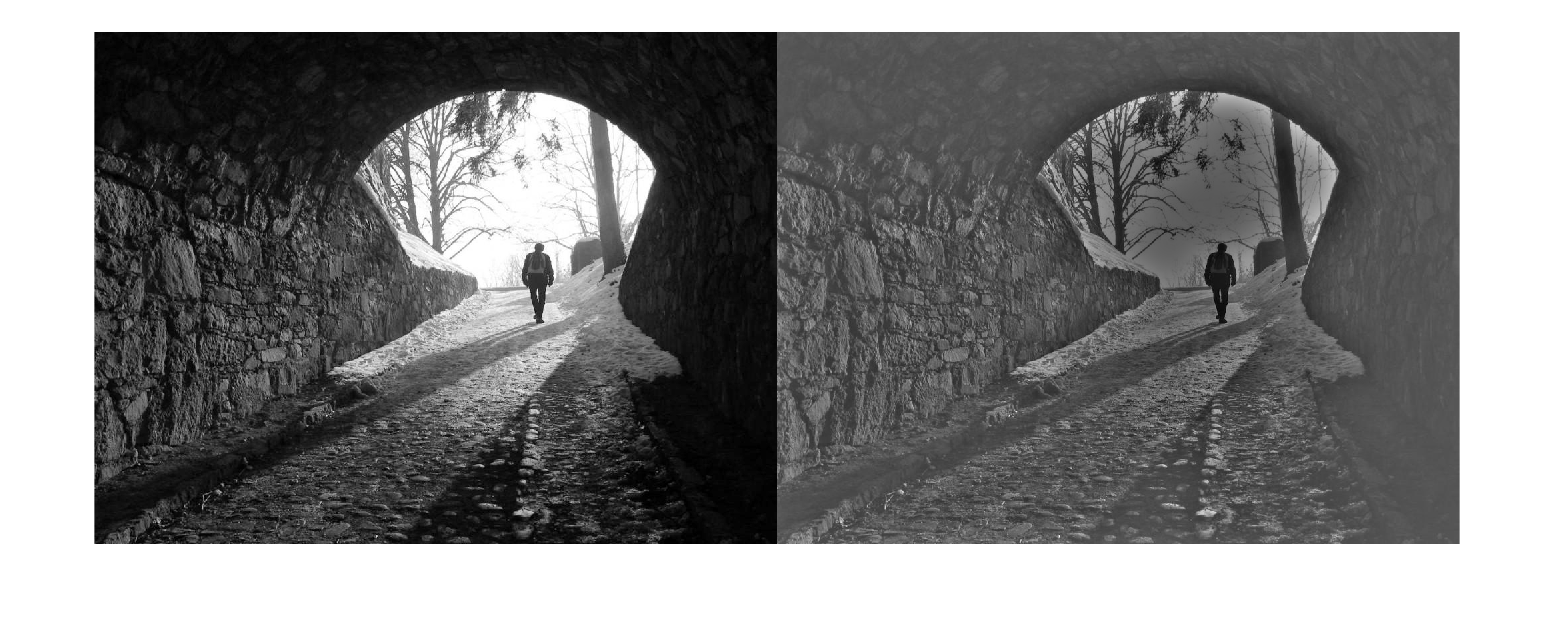

I = imread('C:\Users\Admin\Desktop\original.jpg');
I = im2double(I);

% Get ln(Image)
I = log(1 + I);

% Get M, N for FFT
M = 2*size(I,1) + 1;
N = 2*size(I,2) + 1;

% Create a centered Gaussian Low Pass Filter
sigma = 10;
[X, Y] = meshgrid(1:N,1:M);
centerX = ceil(N/2);
centerY = ceil(M/2);
gaussianNumerator = (X - centerX).^2 + (Y - centerY).^2;
H = exp(-gaussianNumerator./(2*sigma.^2));

% Create High Pass Filter from Low Pass Filter by 1-H
H = 1 - H;

% Uncentered HPF
H = fftshift(H);

% Frequency transform - FFT
If = fft2(I, M, N);

% High Pass Filtering followed by Inverse FFT
Iout = real(ifft2(H.*If));
Iout = Iout(1:size(I,1),1:size(I,2));

% Do exp(I) from log domain
Ihmf = exp(Iout) - 1;

% display the images
imshowpair(I, Ihmf, 'montage')